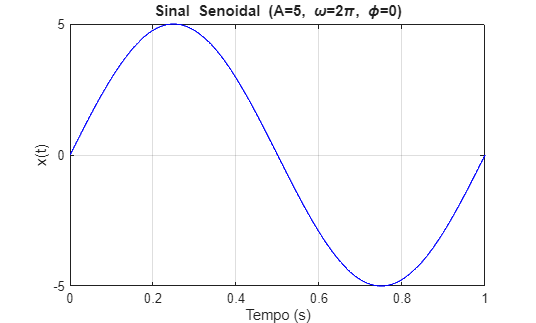

% Exercícios Computacionais - Semana 1
% Aluno: João Vitor Miranda Sousa, N° USP: 14802702

%% Questão 1 - Sinais Senoidais
% Simulação dos sinais x(t) = A * sin(wt + phi), segue abaixo as alternativas:

% (a) A=5, w=2π, φ=0:
t = 0:0.001:1;   % t=1s
A = 5; w = 2*pi; phi = 0;
x1 = A * sin(w*t + phi);

figure;
plot(t, x1, 'b'); grid on;
title('Sinal Senoidal (A=5, \omega=2\pi, \phi=0)');
xlabel('Tempo (s)'); ylabel('x(t)');

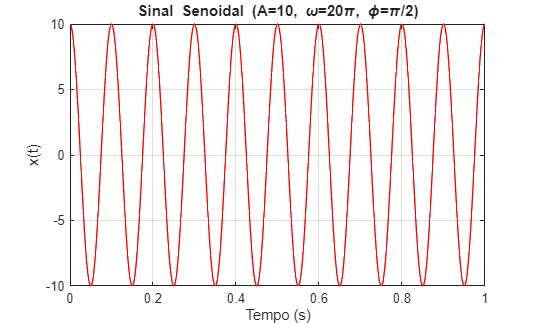



% (b) A=10, w=20π, φ=π/2
t = 0:0.001:1;   % mesmo intervbalo de t
A = 10; w = 20*pi; phi = pi/2;
x2 = A * sin(w*t + phi);

figure;
plot(t, x2, 'r'); grid on;
title('Sinal Senoidal (A=10, \omega=20\pi, \phi=\pi/2)');
xlabel('Tempo (s)'); ylabel('x(t)');

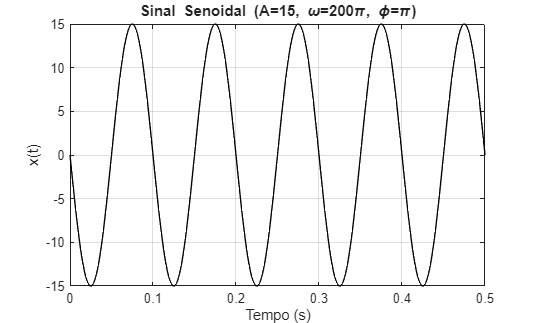



% (c) A=15, w=200π, φ=π
% Frequência muito alta → passo menor e intervalo reduzido
T = (2*pi)/w;          % período do sinal
t = 0:T/100:5*T;       % 100 pontos por período, mostrando 5 períodos
A = 15; phi = pi;
x3 = A * sin(w*t + phi);

figure;
plot(t, x3, 'k'); grid on;
title('Sinal Senoidal (A=15, \omega=200\pi, \phi=\pi)');
xlabel('Tempo (s)'); ylabel('x(t)');

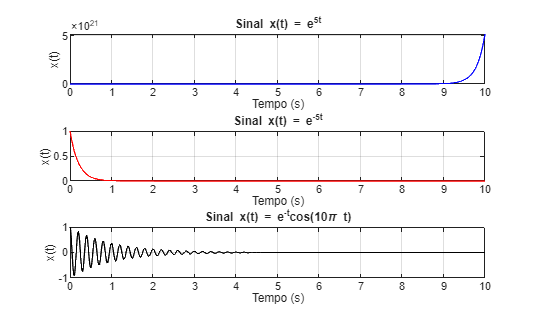



%% Questão 2 - Sinais Exponenciais
% Intervalo de tempo (0 a 10 segundos, passo 0.01), t=10s, ou seja, t∈[0,10]s
t = 0:0.01:10;

% (a) x(t) = e^(5t)
x4 = exp(5*t);

% (b) x(t) = e^(-5t)
x5 = exp(-5*t);

% (c) x(t) = e^(-t) * cos(10πt)
x6 = exp(-t) .* cos(10*pi*t);

% Plotando em subplots
figure;
subplot(3,1,1);
plot(t, x4, 'b'); grid on;
title('Sinal x(t) = e^{5t}');
xlabel('Tempo (s)'); ylabel('x(t)');

subplot(3,1,2);
plot(t, x5, 'r'); grid on;
title('Sinal x(t) = e^{-5t}');
xlabel('Tempo (s)'); ylabel('x(t)');

subplot(3,1,3);
plot(t, x6, 'k'); grid on;
title('Sinal x(t) = e^{-t}cos(10\pi t)');
xlabel('Tempo (s)'); ylabel('x(t)');